% Given data
data = [
    -200    18.52;
    -190    22.826;
    -180    27.096;
    -170    31.335;
    -160    35.543;
    -150    39.723;
    -140    43.876;
    -130    48.005;
    -120    52.11;
    -110    56.193;
    -100    60.256;
    -90     64.3;
    -80     68.325;
    -70     72.335;
    -60     76.328;
    -50     80.306;
    -40     84.271;
    -30     88.222;
    -20     92.16;
    -10     96.086;
    0       100;
    10      103.903;
    20      107.794;
    30      111.673;
    40      115.541;
    50      119.397;
    60      123.242;
    70      127.075;
    80      130.897;
    90      134.707;
    100     138.505;
    110     142.293;
    120     146.068;
    130     149.832;
    140     153.584;
    150     157.325;
    160     161.054;
    170     164.772;
    180     168.478;
    190     172.173;
    200     175.856;
    210     179.528;
    220     183.188;
    230     186.836;
    240     190.473;
    250     194.098;
    260     197.712;
    270     201.314;
    280     204.905
    ];


% Extract temperature and resistance values
temperature = data(:, 1)

temperature =   -200
  -190
  -180
  -170
  -160
  -150
  -140
  -130
  -120
  -110


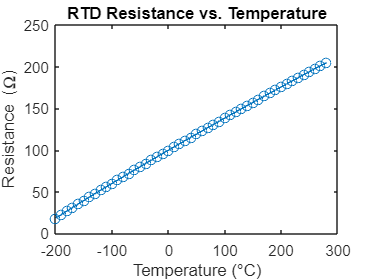

resistance = data(:, 2);

% Plot the data
plot(temperature, resistance, 'o-')
xlabel('Temperature (°C)');
ylabel('Resistance (\Omega)');
title('RTD Resistance vs. Temperature');


% Find the equation
coefficients = polyfit(temperature, resistance, 2);

% Display the polynomial equation
fprintf('Polynomial coefficients: %.6f, %.6f, %.6f\n', coefficients);

Polynomial coefficients: -0.000065, 0.392467, 99.998067



% Given temperature range from 0°C to 100°C
temperature_range = 0:100

temperature_range =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



% Calculate resistance using the polynomial equation
R3 = polyval(coefficients, temperature_range)

R3 =    99.9981  100.3905  100.7827  101.1749  101.5669  101.9588  102.3505  102.7421  103.1336  103.5250  103.9162  104.3073  104.6983  105.0891  105.4798  105.8704  106.2608  106.6511  107.0413  107.4314  107.8213  108.2111  108.6007  108.9903  109.3797  109.7689  110.1581  110.5471  110.9359  111.3247  111.7133  112.1018  112.4901  112.8784  113.2665  113.6544  114.0423  114.4300  114.8175  115.2050  115.5923  115.9795  116.3665  116.7534  117.1402  117.5269  117.9134  118.2998  118.6860  119.0722



% Given resistance values of R1, R2, and R3 (RTD)
R1 = 119

R1 = 119

R2 = 1810

R2 = 1810

R4 = R2

R4 = 1810

V_supply = 4.2

V_supply = 4.2000



% Calculate the output voltage of the Wheatstone bridge
V_out = V_supply * (R2./(R1+R2) - R4./(R3+R4))

V_out =    -0.0392   -0.0384   -0.0376   -0.0368   -0.0359   -0.0351   -0.0343   -0.0335   -0.0327   -0.0319   -0.0311   -0.0302   -0.0294   -0.0286   -0.0278   -0.0270   -0.0262   -0.0254   -0.0246   -0.0238   -0.0230   -0.0222   -0.0214   -0.0206   -0.0198   -0.0189   -0.0181   -0.0173   -0.0165   -0.0157   -0.0149   -0.0141   -0.0133   -0.0125   -0.0117   -0.0110   -0.0102   -0.0094   -0.0086   -0.0078   -0.0070   -0.0062   -0.0054   -0.0046   -0.0038   -0.0030   -0.0022   -0.0014   -0.0006    0.0001


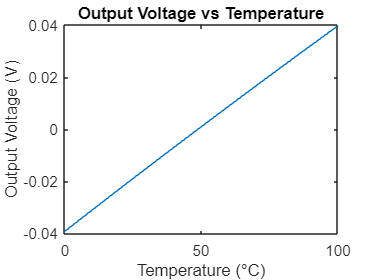


% Plot the output voltage vs temperature
figure;
plot(temperature_range, V_out)
xlabel('Temperature (°C)');
ylabel('Output Voltage (V)');
title('Output Voltage vs Temperature');


% Calculate resistance at 0°C and 100°C using the polynomial equation
R3_at_0C = polyval(coefficients, 0)

R3_at_0C = 99.9981

R3_at_100C = polyval(coefficients, 100)

R3_at_100C = 138.5919


% Calculate output voltage at 0°C and 100°C
V_out_at_0C = V_supply * ((R2 / (R1 + R2)) - (R4 / (R3_at_0C + R4)))

V_out_at_0C = -0.0392

V_out_at_100C = V_supply * ((R2 / (R1 + R2)) - (R4 / (R3_at_100C + R4)))

V_out_at_100C = 0.0396


% Display output voltage at 0°C and 100°C
fprintf('Output Voltage at 0°C: %.4f V\n', V_out_at_0C);

Output Voltage at 0°C: -0.0392 V


fprintf('Output Voltage at 100°C: %.4f V\n', V_out_at_100C);

Output Voltage at 100°C: 0.0396 V


R2

R2 = 1810

R4

R4 = 1810

V_supply

V_supply = 4.2000

% Calculate output voltage at 0°C and 100°C in millivolts
V_out_at_0C_mV = V_out_at_0C * 1000; % Convert volts to millivolts
V_out_at_100C_mV = V_out_at_100C * 1000; % Convert volts to millivolts


% Display output voltage at 0°C and 100°C in microvolts
fprintf('Output Voltage at 0°C: %.4f μV\n', V_out_at_0C_mV);

Output Voltage at 0°C: -39.2067 μV


fprintf('Output Voltage at 100°C: %.4f μV\n', V_out_at_100C_mV);

Output Voltage at 100°C: 39.6233 μV



% Find a polynomial equation describing the relationship between voltage and temperature
degree = 2; % Choose the degree of the polynomial equation
coefficients_voltage = polyfit(temperature_range, V_out, degree);

% Display the coefficients of the polynomial equation
fprintf('Coefficients of the polynomial equation (from highest to lowest order):\n');

Coefficients of the polynomial equation (from highest to lowest order):


disp(coefficients_voltage);

   -0.0000    0.0008   -0.0392

